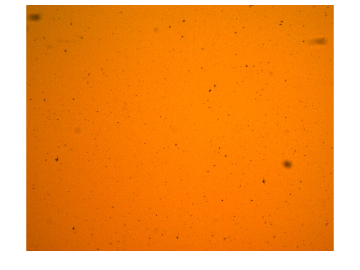

 % Importing the video file.
tic;
inv_path = "~/Downloads/image_processing_ns/ccw-ccw_0.avi";
% inv_path = "~/Downloads/image_processing_ns/60G30hZ REAL_0.avi";
% inv_path = "~/Downloads/image_processing_ns/60G325Hz_without_clamps_start_at_19_sec.avi";
inputVideo = VideoReader(inv_path);
inputVideo_name = split(inv_path, "/");
videoName = split(inputVideo_name(end), "."); 
%calculate frame rate:
frame_rate = inputVideo.FrameRate;

start_time = 0*60+40; %seconds  

stop_time = 1*60+20;

frames = read(inputVideo, [uint16(frame_rate*start_time) uint16(frame_rate*stop_time)]);

imshow(frames(:,:,:,1));

total_time = toc

total_time = 6.8664

% Not needed now!!!
% getting B_field data:
% B_field = zeros(size(frames, 4), 1);
% 
% %Pattern: 7s-8s left(or CW), 3s-3s Delay1, 7s-8s right(or CCW), 4s-5s Delay2, 7s-8s right(or CCW), 2s-2s Delay3
% frames_pattern_field = [ones(8*frame_rate, 1); zeros(3*frame_rate, 1); ones(8*frame_rate, 1); zeros(5*frame_rate, 1); ones(8*frame_rate, 1); zeros(2*frame_rate, 1)];
% % if start_time>=19
% %     for bb = 1 : length(frames_pattern_field) : (stop_time - start_time)*frame_rate
% %         B_field(bb:min(bb+length(frames_pattern_field)-1, size(frames, 4))) = frames_pattern_field(1: min(bb+length(frames_pattern_field)-1, size(frames, 4)) );
% %     end
% % else
% %     for bb=1:(19-start_time)*frame_rate
% %         B_field(bb) = 0;
% %     end
% %     for bb = (19-start_time)*frame_rate : length(frames_pattern_field) : (stop_time - start_time)*frame_rate
% %         B_field(bb:min(bb+length(frames_pattern_field)-1, size(frames, 4))) = frames_pattern_field((19-start_time)*frame_rate: min(bb+length(frames_pattern_field)-1, size(frames, 4)) );
% %     end
% % end
% B_field((19-start_time)*frame_rate+2:end) = frames_pattern_field;
% % B_field = zeros(size(frames, 4), 1);

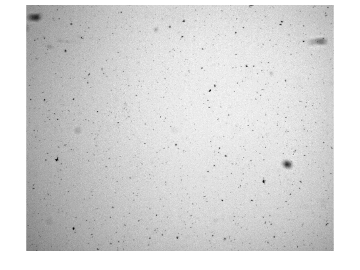

% Converting each frame into grayscale image.
tic;
working_frames = size(frames, 4);
gray_frames = zeros(size(frames, 1), size(frames, 2), working_frames, "uint8");
offset = 0;
for fr_num = 1:working_frames
    gray_frames(:,:,fr_num) = im2gray(frames(:,:,:,fr_num+offset));
end

imshow(gray_frames(:,:,1), []);

toc

Elapsed time is 1.984847 seconds.


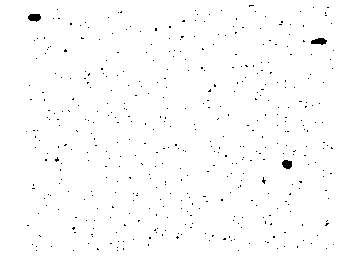

% Binarizing the grayscale frame to detect NS.
% gray_trans = 255- gray_frames;
% imshow(gray_trans(:,:,1), []);    
tic;
bw_frames = zeros(size(gray_frames), 'logical');
for i = 1:size(gray_frames, 3)
%     bw_frames_thresh(:,:,i) = adaptthresh(gray_trans(:,:,i), 0.75, "NeighborhoodSize",17);
%     bw_frames(:,:,i) = imbinarize(gray_trans(:,:,i), bw_frames_thresh(:,:,i));
    bw_frames(:,:,i) = imbinarize(gray_frames(:,:,i), "adaptive", "Sensitivity",0.69);
end
imshow(bw_frames(:,:,1), []);

toc

Elapsed time is 3.705921 seconds.


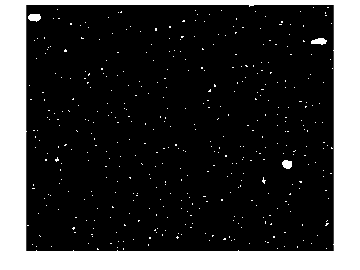

% Just doing ~, to get back backgrd and white NS.
tic;
bw_frames_opp = ~bw_frames;
imshow(bw_frames_opp(:,:,1), []);

clear bw_frames;
toc

Elapsed time is 0.723515 seconds.


% subtracting adjacent frames to know if field is on or off, that is if NS
% are moving or stationary.
% THIS IS FOR LOW DENSITY ON, FOR MORE DENISTY ONE SEE NEXT CELL.
fieldONOFF_Threshold = 2700; %for the less denisty one.
bw_frame_diff = zeros(size(bw_frames_opp, 1), size(bw_frames_opp, 2), size(bw_frames_opp, 3)-1);
fieldOnOff_NNZ = zeros(size(bw_frames_opp, 3), 1);

for frDiff = 1:size(bw_frames_opp, 3)-1
    bw_frame_diff(:,:,frDiff) = bw_frames_opp(:,:,frDiff) - bw_frames_opp(:,:,frDiff+1);
    fieldOnOff_NNZ(frDiff+1) = nnz(bw_frame_diff(:,:,frDiff));
end

fieldOnOFFDir = zeros(size(bw_frames_opp, 3), 1);
for onOffDir = 1:size(fieldOnOff_NNZ,1)
    if fieldOnOff_NNZ(onOffDir) < fieldONOFF_Threshold
        fieldOnOFFDir(onOffDir) = 0;
    elseif fieldOnOff_NNZ(onOffDir) >= fieldONOFF_Threshold
            fieldOnOFFDir(onOffDir) = 1; % CCW(right, +ve velocity_x)
    end
end

% %FOR THE 60G 325HZ VIDEO....
% % subtracting adjacent frames to know if field is on or off, that is if NS
% % are moving or stationary.
% 
% fieldONOFF_Threshold = 12000; % for 60G 325HZ
% % fieldONOFF_Threshold = 15000; % for 60G30Hz_Real_0 video [11000 for 0.7 sensitivity]
% bw_frame_diff = zeros(size(bw_frames_opp, 1), size(bw_frames_opp, 2), size(bw_frames_opp, 3)-1);
% fieldOnOff_NNZ = zeros(size(bw_frames_opp, 3), 1);
% 
% for frDiff = 1:size(bw_frames_opp, 3)-1
%     bw_frame_diff(:,:,frDiff) = bw_frames_opp(:,:,frDiff) - bw_frames_opp(:,:,frDiff+1);
%     fieldOnOff_NNZ(frDiff+1) = nnz(bw_frame_diff(:,:,frDiff));
% end
% 
% fieldOnOFFDir = zeros(size(bw_frames_opp, 3), 1);
% cwCounter = 0;
% cwFlag=0;
% for onOffDir = 1:size(fieldOnOff_NNZ,1)
%     if fieldOnOff_NNZ(onOffDir) < fieldONOFF_Threshold
%         fieldOnOFFDir(onOffDir) = 0;
%         cwFlag=0;
%     elseif fieldOnOff_NNZ(onOffDir) >= fieldONOFF_Threshold
%         if cwFlag==0
%             cwCounter = cwCounter+1;
%             cwFlag=1;
%         end
%         if mod(cwCounter+2,3) == 0
%             fieldOnOFFDir(onOffDir) = -1; % CW(left, -ve velocity_x)
%         else
%             fieldOnOFFDir(onOffDir) = 1; % CCW(right, +ve velocity_x)
%         end
%     end
% end

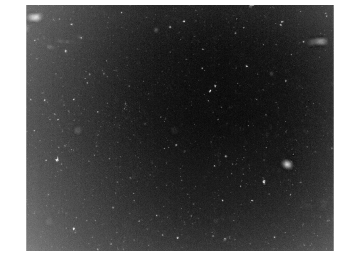

tic
inverted_gray_frames = (255 - gray_frames);
% using grayscale image addition to get background.
gray_backgrdFrame = sum(inverted_gray_frames,3);
% gray_backgrdFrame = gray_frames(:,:, 6*frame_rate);
imshow(gray_backgrdFrame, []);

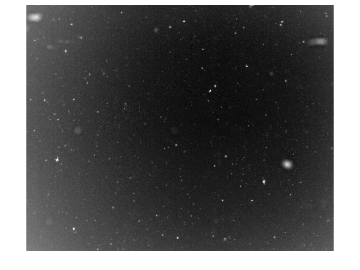


figure
gray_avgBackgrdFrame = cast(round(gray_backgrdFrame/size(inverted_gray_frames, 3)), 'uint8');
imshow(gray_avgBackgrdFrame, []);

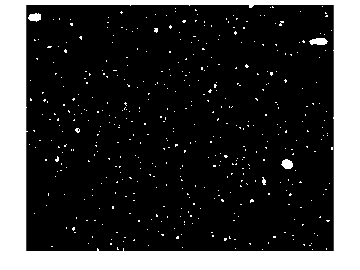

clear gray_backgrdFrame;
%StaticNS - here all the NS in the fr=1 are 0.
staticNS = imbinarize(gray_avgBackgrdFrame, 'adaptive', 'Sensitivity',0.52);
strelDilate = strel("disk", 1);
staticNS = imdilate(staticNS, strelDilate);
figure;
imshow(staticNS, []);

toc

Elapsed time is 2.189400 seconds.


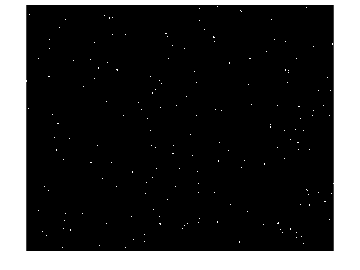

tic
% Just the Nanoswimmers.
% Here subtracting StaticNS from all the frames and taking just the positive values.
gray_processedFrames = (bw_frames_opp - staticNS)>0;
imshow(gray_processedFrames(:,:,458), []);

clear gray_frames;
toc

Elapsed time is 1.985545 seconds.


% using binary image addition to get background.
% backgrdFrame = sum(bw_frames_opp(:,:,((19-start_time)*frame_rate): ((stop_time-start_time)*frame_rate)), 3);
% imshow(backgrdFrame);
% 
% %Static NS 
% se = strel("disk",1);
% se1 = strel("disk",2);
% staticNS = backgrdFrame/((stop_time-start_time)*frame_rate);
% staticNS = staticNS>=0.4;
% erodestaticNS = imerode(staticNS, se);
% dilatestaticNS = imdilate(erodestaticNS, se1);
% imshow(dilatestaticNS, []);

% % processed frames eroding and dilating
% processedFrames = (bw_frames_opp - dilatestaticNS)>0;
% imshow(processedFrames(:,:,600), []);
% 
% %smooth processed frames
% % erodeProcessedFrames = imerode(processedFrames, se);
% erodeprocessedFrames = imerode(processedFrames, se);
% smoothProcessedFrames = imdilate(erodeprocessedFrames, se);
% imshow(smoothProcessedFrames(:,:,600));
% % clear processedFrames;

% Here finding all possible NS, and filtering based on area to get
% potential NS.
tic
for i=1:working_frames
%     cc(i) = bwconncomp(gray_processedFrames(:,:,i));
    cc(i) = bwconncomp(gray_processedFrames(:,:,i));
    cc_props(i).properties = regionprops(cc(i));
end
clear cc;
imshow(frames(:,:,:,offset+1));
hold on;

i_p =1;
% area, centroid1, centroid2, boundary1, boundary2, boundary3, boundary4.
% possible_ns = zeros(size(working_frames, max_ns, 7), 'single')*(-1);

% Here just filtering based on the Area of NS. ---> possible_NS
clear possible_ns;
for i=1:working_frames
    ns_p =1;
    for ns = 1:length(cc_props(i).properties)
        if (cc_props(i).properties(ns).Area > 0 && cc_props(i).properties(ns).Area <= 125) 
            possible_ns(i_p).properties(ns_p) = cc_props(i).properties(ns);
            ns_p = ns_p+1;
        end
    end
    i_p = i_p+1;
end
toc

Elapsed time is 6.546882 seconds.


% Arraging the NS in order of grid. 
% Dividing the frame into 8 by 10 grid, of size(128, 128).
% height = 1024 and width= 1280;
tic;
grid_center_width = linspace(0,10,11)*128;
grid_center_height = linspace(0,8,9)*128;

% create a cell array for arranged NS. It will be a cell array of structs
% in future.
possible_ns_arr = cell(working_frames, (length(grid_center_height)-1)*(length(grid_center_width)-1));
for fr=1:working_frames
    gr_count = 1;
    for h = 1:length(grid_center_height)-1
        for w =1:length(grid_center_width)-1
            i_count = 1;
            for i = 1:length(possible_ns(fr).properties)
                if grid_center_width(w) < possible_ns(fr).properties(i).Centroid(1) && possible_ns(fr).properties(i).Centroid(1) <= grid_center_width(w+1) && grid_center_height(h) < possible_ns(fr).properties(i).Centroid(2) && possible_ns(fr).properties(i).Centroid(2) <= grid_center_height(h+1)
                   possible_ns_arr{fr,gr_count}(i_count, 1) = possible_ns(fr).properties(i); 
                   i_count = i_count+1;
                end
            end
            gr_count = gr_count+1;
        end
    end
end
toc

Elapsed time is 36.787650 seconds.


%testing_griding 
% averg_grid = zeros(working_frames, 80, 2);
% for fr = 1:working_frames
%     for grdd = 1:80
%         for i =1:length(possible_ns_arr{fr, grdd})
%             averg_grid(fr, grdd, 1) = averg_grid(fr, grdd,1) + possible_ns_arr{fr, grdd}(i).Centroid(1)-(grdd/8)*128;
%             averg_grid(fr, grdd, 2) = averg_grid(fr, grdd, 2) + possible_ns_arr{fr, grdd}(i).Centroid(2)-(grdd/10)*128;
%         end
%         averg_grid(fr, grdd) = averg_grid(fr, grdd)./length(possible_ns_arr{fr, grdd});
%     end
% end

% Here just showing all NS (including the detection that are NOT NS.)
% % bounding_box = cat(1, cc_centroid.BoundingBox);
% tic
% for i=1:length(cc_props(1).properties)
%      rectangle("position", cc_props(1).properties(i).BoundingBox, "EdgeColor", "g");
% end
% hold off;
% clear cc_props;
% toc

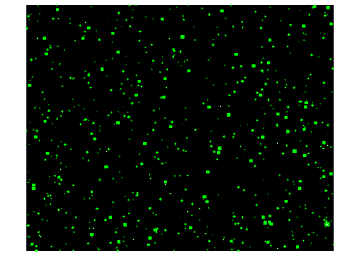

% Here just showing the possible NS after filtering based on area.
tic
n = 1;
% imshow(frame50(:,:,:,n));
imshow(gray_processedFrames(:,:,n));
hold on;
% % bounding_box = cat(1, cc_centroid.BoundingBox);
for z=1:length(possible_ns(n).properties)
     rectangle("position", possible_ns(n).properties(z).BoundingBox, "EdgeColor", "g", "LineWidth",0.8);
     % text(possible_ns(n).properties(z).BoundingBox(1), possible_ns(n).properties(z).BoundingBox(2), string(z), 'Color', 'blue');
end
hold off;

% clear bw_frames;
toc

Elapsed time is 0.212616 seconds.


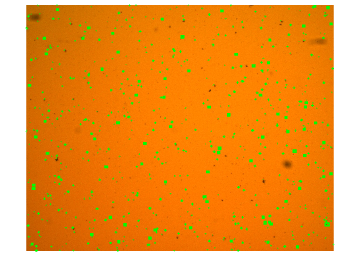

% Here just showing the possible NS after filtering based on area.
tic
n = 1;
% imshow(frame50(:,:,:,n));
imshow(frames(:,:,:,n));
hold on;
% % bounding_box = cat(1, cc_centroid.BoundingBox);
for z=1:length(possible_ns(n).properties)
     rectangle("position", possible_ns(n).properties(z).BoundingBox, "EdgeColor", "g", "LineWidth",0.8);
     % text(possible_ns(n).properties(z).BoundingBox(1), possible_ns(n).properties(z).BoundingBox(2), string(z), 'Color', 'blue');
end
hold off;

% clear bw_frames;
toc

Elapsed time is 0.245872 seconds.


% For tracking the NS, assigning the first coordinate(frame=1) to the traj matrix.
% Define a matrix or cell array for path of nth NS.
tic
max_ns = length(possible_ns(1).properties);
for i = 1:working_frames
    if max_ns< length(possible_ns(i).properties)
        max_ns = length(possible_ns(i).properties);
    end
end
    trajectory_ns= cell(max_ns, 1);
%     trajectory_ns = zeros(max_ns, working_frames+1+1, )
%     % And assign the coordinates from the first frame. 
% for ns =1:length(possible_ns(1).properties)
%     trajectory_ns{ns,1}(1, :) = (possible_ns(1).properties(ns).Centroid);
% end
% And assign the coordinates from the first frame.
% Here the grd is the total number of grid cells that is hieght*width.
% Also, the possible_ns_arr{1, grd}, here 1 refers to the forst frame.
nn_count = 0;
for grd =1:size(possible_ns_arr, 2) 
    for ns = 1:length(possible_ns_arr{1, grd})
    nn_count=nn_count+1;
    trajectory_ns{nn_count,1}(1, 1) = possible_ns_arr{1, grd}(ns).Centroid(1);
    trajectory_ns{nn_count,1}(1, 2) = possible_ns_arr{1, grd}(ns).Centroid(2);
    trajectory_ns{nn_count,1}(1, 3) = possible_ns_arr{1, grd}(ns).Area;
    trajectory_ns{nn_count,1}(1,4:5) = 0; % error, max error
    % trajectory_ns{nn_count, 1}(1, 6) = 1; %dynamic limit distance
    end
end
if nn_count<max_ns 
    for i=(nn_count+1):max_ns
        trajectory_ns{i, 1}(1, 1:2) = [-1 -1];
        trajectory_ns{i, 1}(1, 3) = 0;
        trajectory_ns{nn_count,1}(1,4:5) = 0;
        % trajectory_ns{i, 1}(1, 6) = 0;
    end
end
toc

Elapsed time is 0.027450 seconds.


% % inilialize Kalman Filter
% motionModel = "ConstantVelocity";
% initialLocation = trajectory_ns{n,1}(1,1:2);
% initialErrorEstimate = [1, 25]; % for constant vel. = [location variance, velocity variance]
% motionNoise = [9 25];
% measurementNoise = 16;
% kalmanFilter = configureKalmanFilter("ConstantVelocity", initialLocation, initialErrorEstimate, motionNoise, measurementNoise);

% Implementing the tracking of NS.
tic
limit_distance = 10; % distance square %8
% dynamic_limit_distance = limit_distance;

for fr= 2: working_frames
%     dynamic_limit_distance = 0;

    for ns = 1: max_ns
        % finding min. distance for a NS. get the grid index number for the current "ns", it will be the location to look for the "ns_next".
        grid_index_next = (ceil(trajectory_ns{ns,1}(fr-1, 2)/128)-1)*10 + ceil(trajectory_ns{ns,1}(fr-1, 1)/128);         
        
        % this line gets the index of the surrounding region, to account for the edge case; where the "ns" is at the edge of the ROI, and moves out of the regionin the next frame("ns_next').
        temp_grid_next = [grid_index_next, grid_index_next+1, grid_index_next-1, grid_index_next+10, grid_index_next-10, grid_index_next-11, grid_index_next-9, grid_index_next+9, grid_index_next+11];

        [prev_vel_x, prev_vel_y] = prevAvgVelocityFunct(trajectory_ns{ns, 1}, fr-1, 50);

        % the grid index has to be in [0, 80] including 0, and 80. It can not go outside the size of image.
        if grid_index_next>0 && grid_index_next<=80 % ??? does need ot be added? I think thats why u getting the out of bound error.
            min_distance = 1000; %((trajectory_ns{ns,1}(fr-1, 1) - possible_ns_arr{fr,grid_index_next}(1).Centroid(1))^2 + (trajectory_ns{ns,1}(fr-1, 2) - possible_ns_arr{fr, grid_index_next}(1).Centroid(2))^2)^0.5;
            min_distance_predict = 1000;
            for temp_grid = temp_grid_next
                if temp_grid > 0 && temp_grid <= 80
                    
                    for ns_next = 1:length(possible_ns_arr{fr, temp_grid})
                        % calculating the distance between the prev "ns" in prev "fr-1", and "ns_next" in the current frame "fr". so that which current frame NS to be linked to the prev NS.
%                          if fieldOnOff_NNZ(fr-1) < 10000
                            distance = ((trajectory_ns{ns,1}(fr-1, 1)+prev_vel_x - possible_ns_arr{fr, temp_grid}(ns_next).Centroid(1,1))^2 + (trajectory_ns{ns,1}(fr-1, 2)+prev_vel_y - possible_ns_arr{fr, temp_grid}(ns_next).Centroid(1,2))^2)^0.5;
                            % here finidng the min distance(closest NS) between the a "ns" and NS in "fr".
                            if min_distance >= distance 
                                min_distance = distance;
                                coord_min_x = possible_ns_arr{fr, temp_grid}(ns_next).Centroid(1, 1);
                                coord_min_y = possible_ns_arr{fr, temp_grid}(ns_next).Centroid(1, 2);
                                area_ns = possible_ns_arr{fr, temp_grid}(ns_next).Area;
                            end 
%                          elseif fieldOnOff_NNZ(fr-1) >= 10000
%                             distance_predict = ((trajectory_ns{ns,1}(fr-1, 1)+prev_vel_x - possible_ns_arr{fr, temp_grid}(ns_next).Centroid(1,1))^2 + (trajectory_ns{ns,1}(fr-1, 2)+prev_vel_y - possible_ns_arr{fr, temp_grid}(ns_next).Centroid(1,2))^2)^0.5;
% %                             here finidng the min distance(closest NS) between the a "ns" and NS in "fr".
%                             if min_distance_predict >= distance_predict 
%                                 min_distance_predict = distance_predict;
%                                 coord_min_x = possible_ns_arr{fr, temp_grid}(ns_next).Centroid(1, 1);
%                                 coord_min_y = possible_ns_arr{fr, temp_grid}(ns_next).Centroid(1, 2);
%                                 area_ns = possible_ns_arr{fr, temp_grid}(ns_next).Area;
%                             end
%                         end
                    end

                end
            end

        end
        % [prev_vel_x_dynamic, prev_vel_y_dynamic] =  prevAvgVelocityFunct(trajectory_ns{ns, 1}, fr-1, 20);
        % if fieldOnOff_NNZ(fr-1) >=fieldONOFF_Threshold
        %     dynamic_limit_distance = (prev_vel_x_dynamic^2 + prev_vel_y_dynamic^2)^0.5;
        %     trajectory_ns{ns,1}(fr,6) = ceil(dynamic_limit_distance);
        % else
        %     trajectory_ns{ns, 1}(fr,6) = trajectory_ns{ns,1}(fr-1,6);
        % end

%       area_diff = (area_ns - trajectory_ns{ns,1}(fr-1,3))/trajectory_ns{ns,1}(f-1,3);
         if fieldOnOff_NNZ(fr-1) <fieldONOFF_Threshold % meaning field is off
            if min_distance<= limit_distance 
            % if ns <= length(possible_ns(fr).properties) && min_distance<=limit_distance
                trajectory_ns{ns, 1}(fr, 1) = coord_min_x;
                trajectory_ns{ns, 1}(fr, 2) = coord_min_y;
                trajectory_ns{ns, 1}(fr, 3) = area_ns;
    %            trajectory_ns{ns, 1}(fr, 4) = angle_ns;
            elseif min_distance> limit_distance 
                % elseif ns <= length(possible_ns(fr).properties) && min_distance> limit_distance
                trajectory_ns{ns, 1}(fr, 1) = trajectory_ns{ns,1}(fr-1, 1);
                trajectory_ns{ns, 1}(fr, 2) = trajectory_ns{ns,1}(fr-1, 2);
                trajectory_ns{ns, 1}(fr, 3) = trajectory_ns{ns,1}(fr-1, 3);
        %            trajectory_ns{ns, 1}(fr, 4) = trajectory_ns{ns, 1}(fr-1, 4);
            
            else
                trajectory_ns{ns, 1}(fr, 1:2) = [-1, -1];
                trajectory_ns{ns,1}(fr, 3) = 0;
    %            trajectory_ns{ns,1}(fr, 4) = 0;
            end

         elseif fieldOnOff_NNZ(fr-1) >=fieldONOFF_Threshold % meaning the field if on
             if min_distance<= limit_distance && abs((trajectory_ns{ns,1}(fr-1, 3)-area_ns)/trajectory_ns{ns,1}(fr-1, 3)) <= 0.5
                 % if ns <= length(possible_ns(fr).properties) && min_distance<=limit_distance
                trajectory_ns{ns, 1}(fr, 1) = coord_min_x;
                trajectory_ns{ns, 1}(fr, 2) = coord_min_y;
                trajectory_ns{ns, 1}(fr, 3) = area_ns;
%                 kfLocationNS = predict(kalmanFilter);
%                 kfLocationNS = correct(kalmanFilter, [coord_min_x, coord_min_y]);
    %            trajectory_ns{ns, 1}(fr, 4) = angle_ns;
             elseif min_distance<= limit_distance && abs((trajectory_ns{ns,1}(fr-1, 3)-area_ns)/trajectory_ns{ns,1}(fr-1, 3)) > 0.5
                 % if ns <= length(possible_ns(fr).properties) && min_distance<=limit_distance
                if prev_vel_y<=10 && prev_vel_x<=10
                    trajectory_ns{ns, 1}(fr, 1) = trajectory_ns{ns, 1}(fr-1, 1) + prev_vel_x;
                    trajectory_ns{ns, 1}(fr, 2) = trajectory_ns{ns, 1}(fr-1, 2) + prev_vel_y;
                else
                    trajectory_ns{ns, 1}(fr, 1) = trajectory_ns{ns, 1}(fr-1, 1) + prev_vel_x/abs(prev_vel_x)*limit_distance;
                    trajectory_ns{ns, 1}(fr, 2) = trajectory_ns{ns, 1}(fr-1, 2) + prev_vel_y/abs(prev_vel_y)*limit_distance;
                end
                trajectory_ns{ns, 1}(fr, 3) = area_ns;

            elseif min_distance> limit_distance
                % elseif ns <= length(possible_ns(fr).properties) && min_distance> limit_distance
%                 kfLocationNS = predict(kalmanFilter);
%                 trajectory_ns{ns, 1}(fr, 1) = kfLocationNS(1);
%                 trajectory_ns{ns, 1}(fr, 2) = kfLocationNS(2);
                if prev_vel_y<=10 && prev_vel_x<=10
                    trajectory_ns{ns, 1}(fr, 1) = trajectory_ns{ns, 1}(fr-1, 1) + prev_vel_x;
                    trajectory_ns{ns, 1}(fr, 2) = trajectory_ns{ns, 1}(fr-1, 2) + prev_vel_y;
                else
                    trajectory_ns{ns, 1}(fr, 1) = trajectory_ns{ns, 1}(fr-1, 1) + prev_vel_x/abs(prev_vel_x)*limit_distance;
                    trajectory_ns{ns, 1}(fr, 2) = trajectory_ns{ns, 1}(fr-1, 2) + prev_vel_y/abs(prev_vel_y)*limit_distance;
                end
                trajectory_ns{ns, 1}(fr, 3) = trajectory_ns{ns,1}(fr-1, 3);
    %            trajectory_ns{ns, 1}(fr, 4) = trajectory_ns{ns, 1}(fr-1, 4);
            else
                trajectory_ns{ns, 1}(fr, 1:2) = [-1, -1];
                trajectory_ns{ns,1}(fr, 3) = 0;
    %            trajectory_ns{ns,1}(fr, 4) = 0;
            end 
        end
    end
end
toc

Elapsed time is 35.209767 seconds.


% FIGURE OUT IF THE NS NUMBER INCREASES IN THE NEXT FRAME.

% here trying to get the confidence level(error in tracking) for each NS.
% limit_distance = 1;
tic
for fr= 2: working_frames
    for ns = 1: max_ns
        % finding min. distance for a NS.
%         min_distance = ((trajectory_ns{ns,1}(fr-1, 1) - possible_ns(fr).properties(1).Centroid(1,1))^2 + (trajectory_ns{ns,1}(fr-1, 2) - possible_ns(fr).properties(1).Centroid(1,2))^2)^(0.5);
        min_distance_same_frame = 1000;
        % finding nearest neighbour to current NS.
        
        for closest = max(ns-10, 1): min(ns+10, length(possible_ns(fr).properties))
            close_distance = ((trajectory_ns{ns,1}(fr, 1) - trajectory_ns{closest,1}(fr, 1))^2 + (trajectory_ns{ns,1}(fr, 2) - trajectory_ns{closest,1}(fr, 2))^2)^(0.5);
            if min_distance_same_frame >= close_distance && close_distance ~= 0
                min_distance_same_frame = close_distance;
                closest_ns_index = closest;
                close_mat(ns+fr-1, :) = [fr, ns, [trajectory_ns{ns,1}(fr, 1), trajectory_ns{ns, 1}(fr, 2)], closest_ns_index, [trajectory_ns{closest_ns_index,1}(fr, 1), trajectory_ns{closest_ns_index, 1}(fr, 2)]];
            end
        end
         assigned_diff = ((trajectory_ns{ns, 1}(fr, 1) - trajectory_ns{ns, 1}(fr-1, 1))^2 + (trajectory_ns{ns, 1}(fr, 2) - trajectory_ns{ns, 1}(fr-1, 2))^2) + ((trajectory_ns{closest_ns_index, 1}(fr, 1) - trajectory_ns{closest_ns_index, 1}(fr-1, 1))^2 + (trajectory_ns{closest_ns_index, 1}(fr, 2) - trajectory_ns{closest_ns_index, 1}(fr-1, 2))^2);
         cross_diff = ((trajectory_ns{ns, 1}(fr, 1) - trajectory_ns{closest_ns_index, 1}(fr-1, 1))^2 + (trajectory_ns{ns, 1}(fr, 1) - trajectory_ns{closest_ns_index, 1}(fr-1, 2))^2) + ((trajectory_ns{closest_ns_index, 1}(fr, 1) - trajectory_ns{ns, 1}(fr-1, 1))^2 + (trajectory_ns{closest_ns_index, 1}(fr, 2) - trajectory_ns{ns, 1}(fr-1, 2))^2);
         error_level = assigned_diff/cross_diff;
         trajectory_ns{ns, 1}(fr, 4) = error_level;
%          factor_area = 0.5;
         factor_area = 0.2;
%          factor_displacement = 0.5;
         factor_displacement = 0.8;
         disp_x = (trajectory_ns{ns,1}(fr, 1) - trajectory_ns{ns,1}(fr-1, 1))^2;
         disp_y = (trajectory_ns{ns,1}(fr, 2) - trajectory_ns{ns,1}(fr-1, 2))^2;
         error_level_2 = factor_area*abs(trajectory_ns{ns,1}(fr, 3) - trajectory_ns{ns,1}(fr-1, 3))/trajectory_ns{ns,1}(fr-1,3) + factor_displacement*((disp_x + disp_y)/(1.5*trajectory_ns{ns,1}(fr-1,3)))^0.5;
         trajectory_ns{ns, 1}(fr, 5) = error_level_2;

    end

end
toc

Elapsed time is 4.630716 seconds.


% calculating the velocity and angle of NS.
tic
velocity_x = zeros(size(trajectory_ns, 1), working_frames);
velocity_y = zeros(size(trajectory_ns, 1), working_frames);
angle_ns = zeros(size(trajectory_ns, 1), working_frames);
for i = 2:working_frames
    for j =1:size(trajectory_ns, 1)
        velocity_x(j, i) = (trajectory_ns{j, 1}(i, 1) - trajectory_ns{j, 1}(i-1, 1));
        velocity_y(j ,i) = (trajectory_ns{j, 1}(i, 2) - trajectory_ns{j, 1}(i-1, 2)); 
        angle_ns(j, i) = atan(velocity_y(j, i)/velocity_x(j, i));

    end
end
toc

Elapsed time is 0.154176 seconds.


% mkdir("./good_tracked_NS/"+start_time+"_"+stop_time+"Seconds");
mkdir("./"+videoName(1)+"/"+start_time+"_"+stop_time+"Seconds");

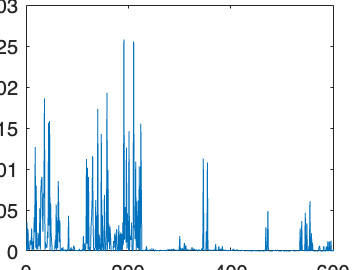

% Here just plotting the error vs frame number.
tic
% error plot
ns_number=1;
fr_plot = linspace(1, length(trajectory_ns{1}), length(trajectory_ns{1}));
plot(fr_plot, trajectory_ns{ns_number}(:,4))

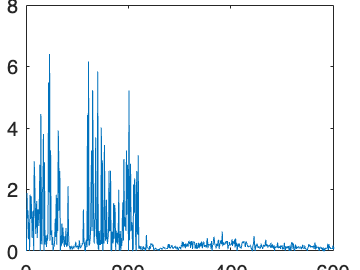

% for i = 1:length(trajectory_ns{1}(: ,4))-1
% derivative_trajec_error1(i, 1) = trajectory_ns{1}(i+1, 4) - trajectory_ns{1}(i, 4);
% end
% derivative_trajec_error1(length(trajectory_ns{1}(: ,4)), 1) = 0;
% plot(fr_plot, derivative_trajec_error1);

plot(fr_plot, trajectory_ns{ns_number}(:,5))

% error 
error2_count = trajectory_ns{ns_number}(:, 5) > 0.8;
per_error2 = nnz(error2_count)/length(error2_count)*100

per_error2 = 13.3111

toc

Elapsed time is 1.050895 seconds.


% good tracking or not based on error2
error2CountFrames = zeros(length(trajectory_ns), working_frames);
percentError2Frames = zeros(length(trajectory_ns), 2);
for e = 1:length(trajectory_ns)
    error2CountFrames(e,:) = trajectory_ns{e}(:,5) > 2.5;
    percentError2Frames(e,1) = nnz(error2CountFrames(e, :))/working_frames*100;
    percentError2Frames(e,2) = max(trajectory_ns{e}(:,5));
end

modifiedVelX = velocity_x.*fieldOnOFFDir'; % modified velocity in x direction is all intensionally made positive and zero where the field is off.
notflippedVelX = smoothdata(velocity_x.*(fieldOnOFFDir~=0)',2, "movmean", 10);
smoothVelX = smoothdata(modifiedVelX,2, "movmean", 10); 
smoothVelX = round(smoothVelX*100)/100;
% modifiedVelY = velocity_y.*fieldOnOFFDir';
% smoothVelY = smoothdata(modifiedVelY,2, "movmean", 10);
manual_noise = 0.12;
bistabilityPercent = sum((smoothVelX<-0.05),2)/nnz(fieldOnOFFDir)*100;

noiseVel = zeros(size(smoothVelX,1), 1);
avgVelX = sum(smoothVelX,2)/size(smoothVelX,2);
noiseVel = (sum((smoothVelX - avgVelX).^2, 2)/size(smoothVelX,2)).^0.5;
total_noise =0;
for n_noise= 1:length(percentError2Frames)
    if percentError2Frames(n_noise)<=3.6
        total_noise = total_noise + noiseVel(n_noise);
    end
end
total_noise=total_noise/length(noiseVel);

avgVelocityX_CW = sum(abs(-1*smoothVelX(:,fieldOnOFFDir == -1)),2)/nnz(fieldOnOFFDir<0); %this is avg speed but named velocity.
avgVelocityX_CCW = sum(abs(smoothVelX(:,fieldOnOFFDir == 1)),2)/nnz(fieldOnOFFDir>0); %this is avg speed but named velocity.
clear goodTrackNSIndex;
counterNS=1;
for ns = 1:length(percentError2Frames)
    % max vel jump for 60G325Hz_without_clamps_start_at_19_sec video is <=3.6(very lenient)
    % For the 60G30Hz_REAL_0 video is can be taken < 2.9 if want approx no
    % jumping included.
    % (avgVelocityX_CW(ns) >= manual_noise) &&
    if (avgVelocityX_CCW(ns) >= manual_noise) && (percentError2Frames(ns, 2) <=3) && ((sum(trajectory_ns{ns,1}(:,1) > 0)/working_frames)==1 && (sum(trajectory_ns{ns,1}(:,1) <= size(frames, 2))/working_frames)==1 && (sum(trajectory_ns{ns,1}(:,2) > 0)/working_frames)==1 && (sum(trajectory_ns{ns,1}(:,2) <= size(frames, 1))/working_frames)==1)
        goodTrackNSIndex(counterNS,:) = [ns, percentError2Frames(ns,:), avgVelocityX_CW(ns), avgVelocityX_CCW(ns), bistabilityPercent(ns)];
        counterNS = counterNS+1;
    end
end
% goodTracking table [NS number, [percentError, maxError/velocity], avgVelX_CW, avgVelX_CCW, bistability_percent]

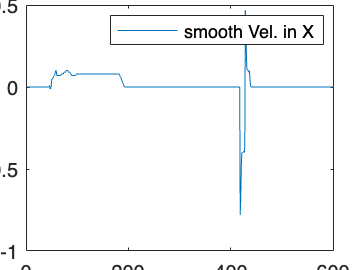

% just plotting here VELOCITY AND ANGLE HERE.
ns_number = 117;
plot(fr_plot, smoothVelX(ns_number, :));
xlabel("Frame Number");
ylabel("Velocity ( µm/sec )");
hold on;
% plot(fr_plot, velocity_x(ns_number, :));
% plot(fr_plot, angle_ns(ns_number, :));
legend("smooth Vel. in X"); %"Vel. in X"
hold off;

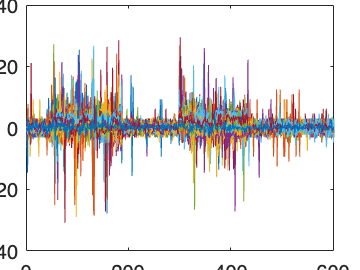

% 4x-> 4mmx 4mm. So, 1 pixel = 4000/1280 = 3.125um.
pixel2um = 3.125;
% plotting velocity and angel separately.
for ns = 1:length(goodTrackNSIndex)
    ns_number = goodTrackNSIndex(ns, 1);
    plot(fr_plot, velocity_x(ns_number, :)*pixel2um);
    ylabel("Velocity in X direction ( µm/sec )");
    xlabel("Frame Number");
    hold on;
end
saveas(gcf, "./"+ videoName(1)+"/"+start_time+"_"+stop_time+"Seconds/"+start_time+"-"+stop_time+"Sec_VelX.png");
hold off;

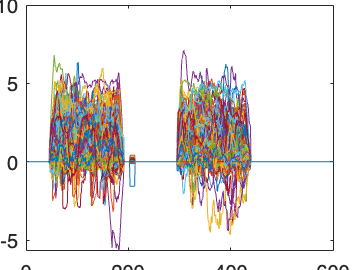

for ns = 1:length(goodTrackNSIndex)
    ns_number = goodTrackNSIndex(ns, 1);
    plot(fr_plot, notflippedVelX(ns_number, :)*pixel2um);
    ylabel("Velocity in X direction ( µm/sec )");
    xlabel("Frame Number");
    hold on;
end
saveas(gcf, "./"+ videoName(1)+"/"+start_time+"_"+stop_time+"Seconds/"+start_time+"-"+stop_time+"Sec_notFlippedVelX.png");
hold off;

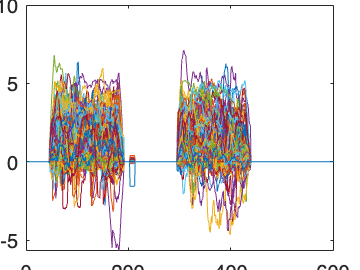

for ns = 1:length(goodTrackNSIndex)
    ns_number = goodTrackNSIndex(ns, 1);
    plot(fr_plot, smoothVelX(ns_number, :)*pixel2um);
    ylabel("Smoothed Velocity in X direction ( µm/sec )");
    xlabel("Frame Number");
    hold on;
end
saveas(gcf, "./"+ videoName(1)+"/"+start_time+"_"+stop_time+"Seconds/"+start_time+"-"+stop_time+"Sec_smoothVelX.png");
hold off;

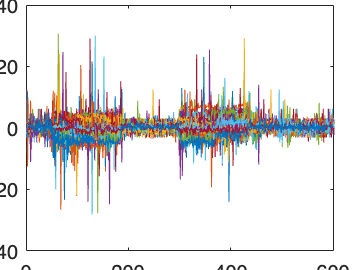

for ns = 1:length(goodTrackNSIndex)
    ns_number = goodTrackNSIndex(ns, 1);
    plot(fr_plot, velocity_y(ns_number, :)*pixel2um);
    ylabel("Velocity in Y direction ( µm/sec )");
    xlabel("Frame Number");
    hold on;
end
saveas(gcf, "./"+ videoName(1)+"/"+start_time+"_"+stop_time+"Seconds/"+start_time+"-"+stop_time+"Sec_VelY.png");
hold off;

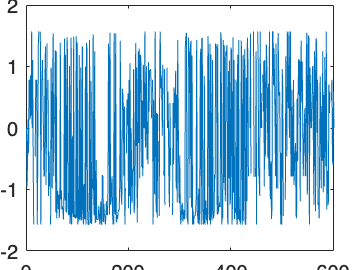

plot(fr_plot, angle_ns(ns_number, :));
ylabel("Angle");
xlabel("Frame Number");

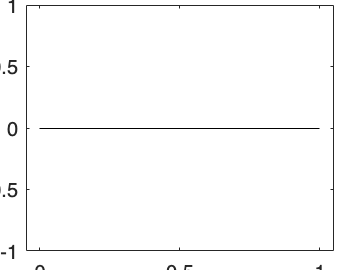

histogram(goodTrackNSIndex(:,4)*pixel2um)
title("CW");% CW
xlabel("Average Speed- CW ( µm/sec )");
ylabel("Number of NS")
saveas(gcf, "./"+ videoName(1)+"/"+start_time+"_"+stop_time+"Seconds/"+start_time+"-"+stop_time+"Sec_histoCW.png");

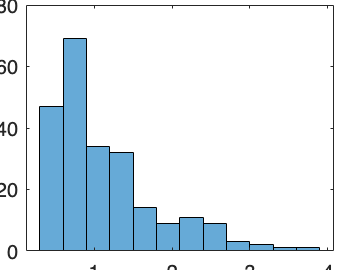

histogram(goodTrackNSIndex(:,5)*pixel2um) %CCW
xlabel("Average Speed- CCW ( µm/sec )")
ylabel("Number of NS")
title("CCW");
saveas(gcf, "./"+ videoName(1)+"/"+start_time+"_"+stop_time+"Seconds/"+start_time+"-"+stop_time+"Sec_histoCCW.png");

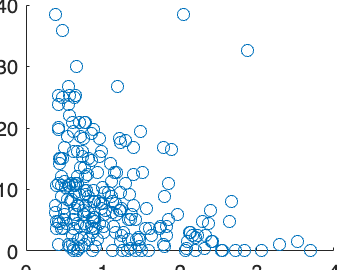

% scatter((goodTrackNSIndex(:,5)+goodTrackNSIndex(:,4))/2, goodTrackNSIndex(:,6));
scatter(goodTrackNSIndex(:,5)*pixel2um, goodTrackNSIndex(:,6)); % THIS FOR LESS DENSITY ON.
xlabel("Average Speed Range ( µm/sec )");
ylabel("Percentage Bistability");
saveas(gcf, "./"+ videoName(1)+"/"+start_time+"_"+stop_time+"Seconds/"+start_time+"-"+stop_time+"Sec_Vel_bistab.png");

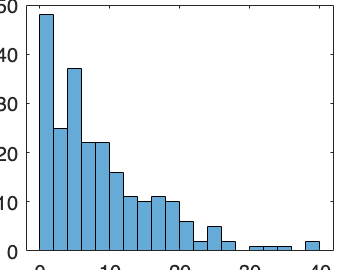

%save goodNS variable
save("./"+ videoName(1)+"/"+start_time+"_"+stop_time+"Seconds/"+start_time+"-"+stop_time+"Sec_goodNS_bistab.mat", "goodTrackNSIndex");
% number of NS showing bistability.
threshold_bistab_Per = 25;
numNS_bistab = sum(goodTrackNSIndex(:,6)>=threshold_bistab_Per);
numNS_bistablePercent = sum(goodTrackNSIndex(:,6)>=threshold_bistab_Per)/length(goodTrackNSIndex(:,6))*100;

%histogram for number of NS showing range of bistability.
histogram(goodTrackNSIndex(:,6), 20);
xlabel("Percentage Bistability Range");
ylabel("Number of NS")
saveas(gcf, "./"+ videoName(1)+"/"+start_time+"_"+stop_time+"Seconds/"+start_time+"-"+stop_time+"Sec_histo_num_bistab.png");

% Here just exporting the frames with markers on NS as a video file.
tic
ns_number =117;
name = split(inputVideo_name(end), ".");
% for nn = 1:length(goodTrackNSIndex)
%      ns_number = goodTrackNSIndex(nn, 1);

% videofile = VideoWriter("good_tracked_NS/"+start_time+"_"+stop_time+"Seconds/pervel_"+ns_number+"_output_track_"+name(1)+".mp4",'MPEG-4');
videofile = VideoWriter("./"+ videoName(1)+"/"+start_time+"_"+stop_time+"Seconds/pervel_"+ns_number+"_output_track_"+name(1)+".mp4",'MPEG-4');
videofile.FrameRate = 15;
% open the videofile
open(videofile);
% write the frames to the video
height = 15;
width = 15;
 %1675 74 73 69(limit_distance issue); 250 252
for i=1:working_frames
    photo = frames(:,:,:,i);
     % for nn = 1:length(goodTrackNSIndex)
     %     ns_number = goodTrackNSIndex(nn,1);
        photo = insertShape(photo, "rectangle", [(trajectory_ns{ns_number}(i, 1)-width/2) (trajectory_ns{ns_number}(i, 2)-height/2) width height], Color="green", LineWidth=2);
        output_frame = insertText(photo, [(size(frames, 1) - 40) 25], i);
     % end
    if fieldOnOFFDir(i) == 0
        output_frame = insertText(output_frame, [(size(frames, 1) - 10) 25], "delay");
    elseif fieldOnOFFDir(i) == 1
        output_frame = insertText(output_frame, [(size(frames, 1) - 10) 25], "CCW");
    elseif fieldOnOFFDir(i) == -1
        output_frame = insertText(output_frame, [(size(frames, 1) - 10) 25], "CW");
    end
    writeVideo(videofile, output_frame);
    clear photo;
end

% 7s- left(or CW), 3s-Delay1, 7s- right(or CCW), 4s- Delay2, 7s- right(or CCW), 2s-Delay3
% close the videofile
close(videofile);
 % end
toc

Elapsed time is 6.902834 seconds.


tic
videofile = VideoWriter("./"+ videoName(1)+"/"+start_time+"_"+stop_time+"Seconds/pervel_"+ns_number+"_output_track_bw"+name(1)+".mp4",'MPEG-4');
videofile.FrameRate = 15;
% open the videofile
open(videofile);
% write the frames to the video
height = 20;
width = 20;
% ns_number = 10;
for i=1:length(possible_ns)
    photo = double(gray_processedFrames(:,:,i));
    output_frame_shape = insertShape(photo, "rectangle", [(trajectory_ns{ns_number}(i, 1)-width/2) (trajectory_ns{ns_number}(i, 2)-height/2) width height], Color="green", LineWidth=3);
    output_frame = insertText(output_frame_shape, [(size(gray_processedFrames, 1) - 40) 25], i);
    if fieldOnOFFDir(i) == 0
        output_frame = insertText(output_frame, [(size(frames, 1) - 10) 25], "delay");
    elseif fieldOnOFFDir(i) == 1
        output_frame = insertText(output_frame, [(size(frames, 1) - 10) 25], "CCW");
    elseif fieldOnOFFDir(i) == -1
        output_frame = insertText(output_frame, [(size(frames, 1) - 10) 25], "CW");
    end
    writeVideo(videofile, output_frame);
    clear photo;
end
% close the videofile
close(videofile);
toc

Elapsed time is 12.617924 seconds.


% tic
% videofile = VideoWriter("output_track_line"+name(1)+".mp4",'MPEG-4');
% videofile.FrameRate = 45;
% % open the videofile
% open(videofile);
% % write the frames to the video
% height = 20;
% width = 20;
% % ns_number = 10;
% traj_coord = [trajectory_ns{ns_number}(1,1), trajectory_ns{ns_number}(1,2)];
% for i=2:length(possible_ns)
%     photo = (frames(:,:,:,i));
%     traj_coord(i,:) = [trajectory_ns{ns_number}(i, 1) trajectory_ns{ns_number}(i, 2)];
%      output_frame_shape = insertShape(photo, "line", traj_coord, Color="green", LineWidth=1);
%      output_frame = insertText(output_frame_shape, [(size(bw_frames, 1) - 40) 25], i);
%      writeVideo(videofile, output_frame);
%      clear photo;
% end
% % close the videofile
% close(videofile);
% toc

% avg_velocity_x = zeros(size(velocity_x,1), 1);
% direction_avg_velocity_x = zeros(size(velocity_x,1), 1); % 1 for posituve and 0 for negative
% for i=1:size(velocity_x,1)
%     avg_velocity_x(i, 1) = sum(velocity_x(i,:))/size(velocity_x,2); 
% end
% direction_avg_velocity_x(avg_velocity_x > 0) = 1;
% direction_avg_velocity_x(avg_velocity_x < 0) = 0;
% y_dir_vel = linspace(1, length(direction_avg_velocity_x), length(direction_avg_velocity_x));
% scatter(y_dir_vel, direction_avg_velocity_x)

% OUTPUT of possibleNS to feed to MAGIK for traning.
% sz_feedMat = 0;
% for fr=1:working_frames
%     sz_feedMat = sz_feedMat + length(possible_ns(fr).properties);
% end
% 
% feedingMatMagik = zeros(sz_feedMat, 6);
% counter_feedMat = 1;
% for fr=1:working_frames
%     for ns=1:length(possible_ns(fr).properties)
%         feedingMatMagik(counter_feedMat, 1) = possible_ns(fr).properties(ns).Centroid(1);
%         feedingMatMagik(counter_feedMat, 2) = possible_ns(fr).properties(ns).Centroid(2);
%         feedingMatMagik(counter_feedMat, 3) = fr-1;
%         feedingMatMagik(counter_feedMat, 4:6) = 0;
%         counter_feedMat = counter_feedMat+1;
%     end
% 
% end

% % get trajectoryNS index from the coordinate(x,y) NS.
% find_X = 871;
% find_Y = 357;
% indexx = 10*uint16(find_Y/128-1) + ceil(find_X/128);
% sum_ns = 0;
% for i=1:indexx-1
% sum_ns = sum_ns + length(possible_ns_arr{1,i});
% end

% function theta = angleNS(delta_y, delta_x)
% theta = 0;
%     if delta_y > 0 && delta_x > 0
%         theta  = atand(delta_y/delta_x);
%     elseif delta_y > 0 && delta_x < 0
%         theta = 180 + atand(delta_y/delta_x);
%     elseif delta_y < 0 && delta_x < 0
%         theta = 180 + atand(delta_y/delta_x);
%     elseif delta_y < 0 && delta_x > 0
%         theta = 360 + atand(delta_y/delta_x);
%     end
% end

% Some old now not used, sorting of NS based on distance from origin.   
% tic;
% max_ns = length(possible_ns(1).properties);
% for i = 1:working_frames
%     if max_ns< length(possible_ns(i).properties)
%         max_ns = length(possible_ns(i).properties);
%     end
% end
% centro_1 = zeros(working_frames, max_ns, 2, 'single');
% for fr = 1:working_frames
%     for i = 1:length(possible_ns(fr).properties)
%         centro_1(fr, i, :) = possible_ns(fr).properties(i).Centroid;
%     end
% end
% % sorting.
% dist_1 = centro_1(:,:,1).^2+ centro_1(:,:,2).^2;
% indexx = zeros(size(dist_1));
% for fr =1:working_frames
%     [~, indexx(fr, :)] = sort(dist_1(fr, :), 'descend');
% end
% for fr = 1:working_frames
%     for j =1:length(possible_ns(fr).properties)
%         possible_ns_arr(fr).properties(j) = possible_ns(fr).properties(indexx(fr,j));
%     end
% end
% toc

This funciton gives avergae velocity over last n frames.

function [prevAvgVelX, prevAvgVelY] = prevAvgVelocityFunct(trajectoryNS, fr, numFrames)
% Here trajectoryNS is the trajectory of the nth Nanoswimmer for which the prev_velocity to be calculated.
% Here fr is current frames
% numFrames is the number of frames for which prev_velocity is to be calculated.
        if fr>numFrames
            prevAvgVelX = 0;
            prevAvgVelY = 0;
            for i=fr-numFrames:fr-1
                prevAvgVelX = prevAvgVelX + trajectoryNS(i+1,1) - trajectoryNS(i,1);
                prevAvgVelY = prevAvgVelY + trajectoryNS(i+1,2) - trajectoryNS(i,2);
            end
        elseif fr==1 || fr==2
            prevAvgVelX = 0;
            prevAvgVelY = 0;
        else
            prevAvgVelX = 0;
            prevAvgVelY = 0;
            for i=1:fr-1
                prevAvgVelX = prevAvgVelX + trajectoryNS(i+1,1) - trajectoryNS(i,1);
                prevAvgVelY = prevAvgVelY + trajectoryNS(i+1,2) - trajectoryNS(i,2);
            end
        end
        prevAvgVelY = prevAvgVelY/numFrames;
        prevAvgVelX = prevAvgVelX/numFrames;
end